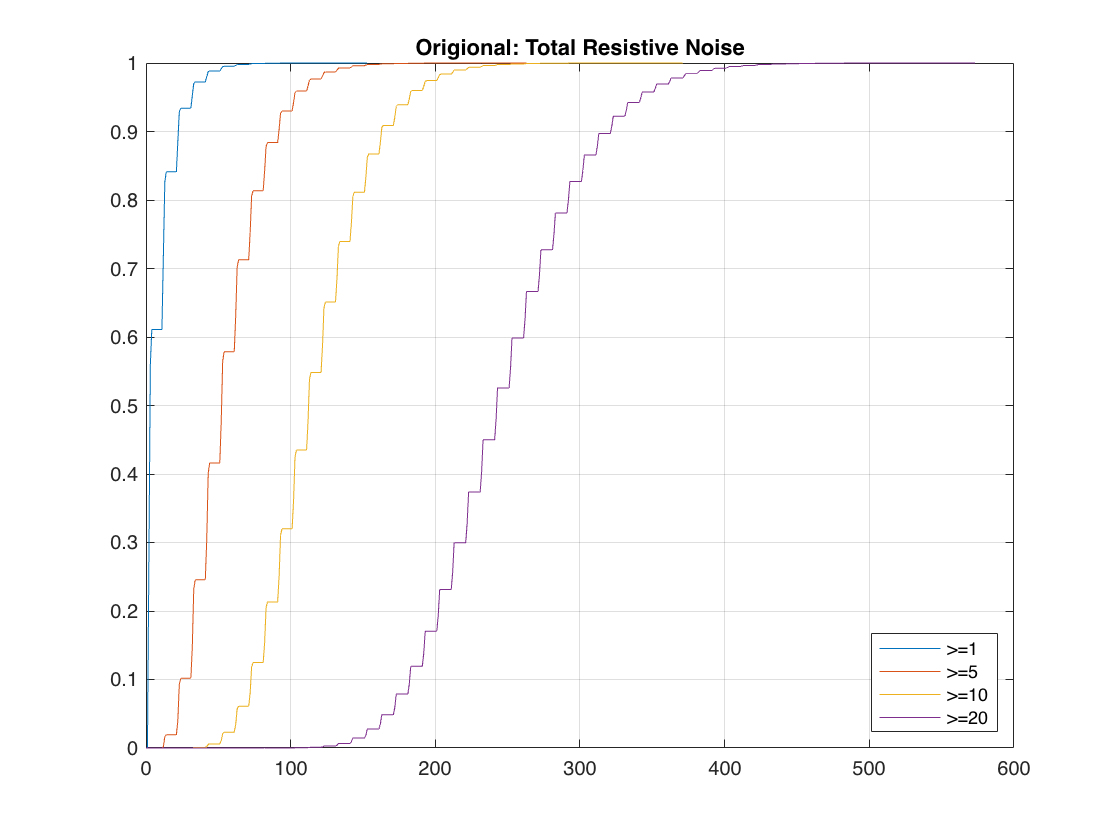

data = csvread('Data/Riley/Burst1.csv');
resist_riley_1_x=data(1:2:end);
resist_riley_1_y=data(2:2:end);

data = csvread('Data/Riley/Burst5.csv');
resist_riley_5_x=data(1:2:end);
resist_riley_5_y=data(2:2:end);

data = csvread('Data/Riley/Burst10.csv');
resist_riley_10_x=data(1:2:end);
resist_riley_10_y=data(2:2:end);

data = csvread('Data/Riley/Burst20.csv');
resist_riley_20_x=data(1:2:end);
resist_riley_20_y=data(2:2:end);

plot(resist_riley_1_x,resist_riley_1_y, ...
     resist_riley_5_x,resist_riley_5_y, ...
     resist_riley_10_x,resist_riley_10_y, ...
     resist_riley_20_x,resist_riley_20_y);
grid on;
title("Origional: Total Resistive Noise");
legend(">=1",">=5",">=10",">=20","Location","southeast");

Because all couters are similar, then the probability of each router contributing to noise is:


$$\sqrt[4]{P_{\mathrm{Total}} }=P_{\mathrm{Single}}$$


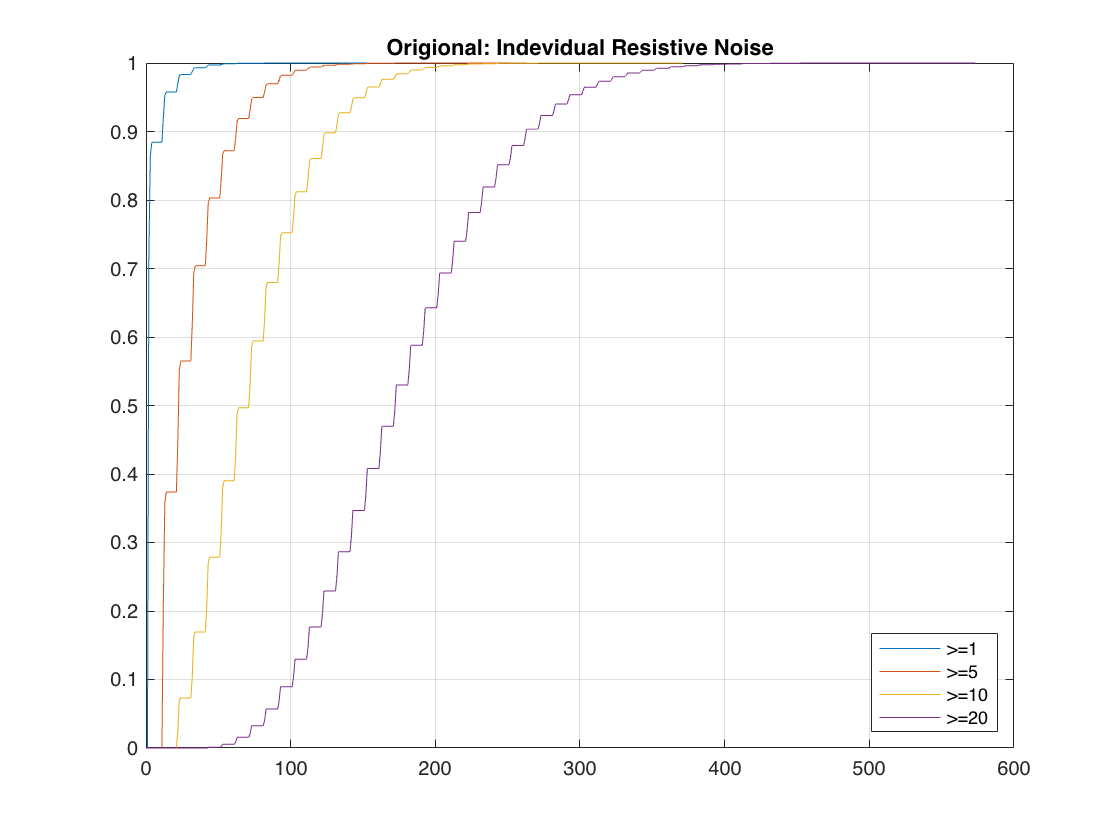

data = csvread('Data/Riley/Burst1.csv');
resist_riley_1_y=nthroot(resist_riley_1_y, 4);

data = csvread('Data/Riley/Burst5.csv');
resist_riley_5_y=nthroot(resist_riley_5_y, 4);

data = csvread('Data/Riley/Burst10.csv');
resist_riley_10_y=nthroot(resist_riley_10_y, 4);

data = csvread('Data/Riley/Burst20.csv');
resist_riley_20_y=nthroot(resist_riley_20_y, 4);

plot(resist_riley_1_x,resist_riley_1_y, ...
     resist_riley_5_x,resist_riley_5_y, ...
     resist_riley_10_x,resist_riley_10_y, ...
     resist_riley_20_x,resist_riley_20_y);
grid on;
title("Origional: Indevidual Resistive Noise");
legend(">=1",">=5",">=10",">=20","Location","southeast");